# Deep Learning for Classification on the MNIST Dataset

The MNIST Dataset contains handwritten digits from 0 through 9. We will use this exercise to learn how to create and train a deep network to classify these digits.

## Are You in the Correct Directory?

% Run this to check
if isfolder('03-AdditionalFiles')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

## Download and Prepare Data

The MNIST dataset contains 70,000 handwritten digits with labels 0-9. The data is broken down as follows:

- 60,000 training images

- 10,000 test images

Run this section to download and prepare the data for this example:

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

## View Images from Dataset

The helper function below displays 25 random images from the dataset using the montage function.

viewMNISTMontage(labelsTrain,imgDataTrain)

## Create Network Architecture

The [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) (DND) is an app that provides a graphical interface creating and training deep networks. 

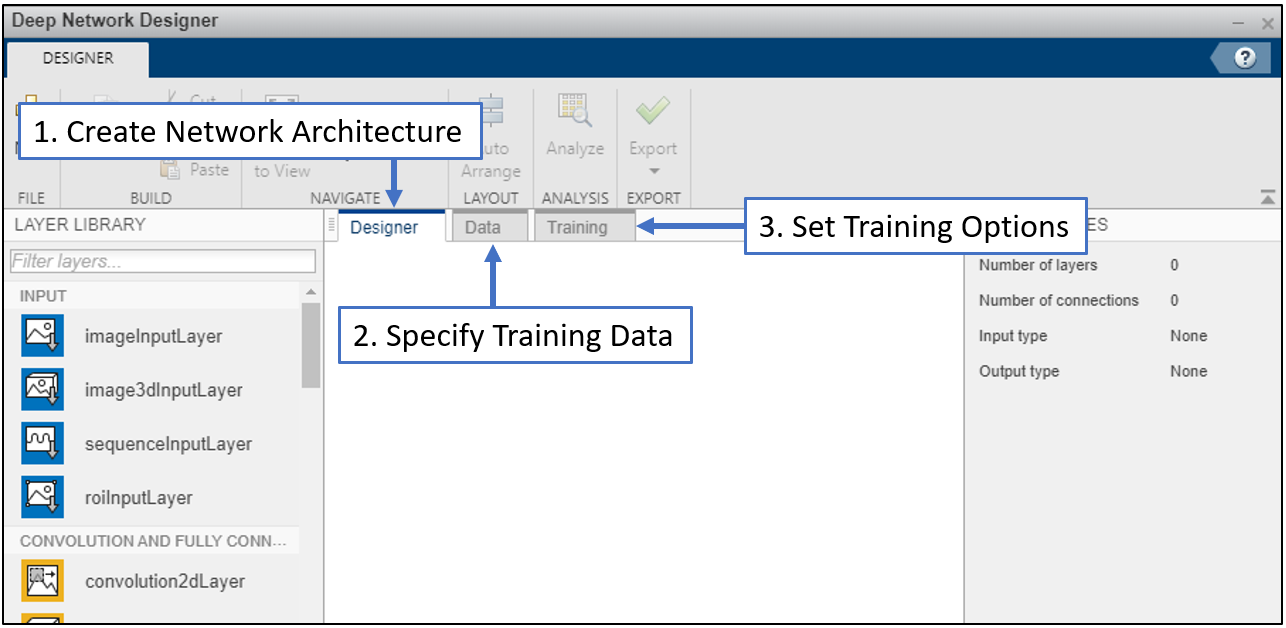

deepNetworkDesigner % Only supported in Google Chrome

Using a different browser? Jump to **THIS** section.

#### Create Architecture with DND (Chrome Only)

Select "Blank Network". Create the architecture shown below in the "Designer" tab. Use the parameters shown in the diagram. 

To view the image in a separate window, download the image [**HERE**](https://1.bp.blogspot.com/-GuDvg1RaQlo/Xz7mlqukerI/AAAAAAAAvMs/2r8TMe7R500QcK9rXrTDLZGnAIMTQPd6wCLcBGAsYHQ/d/NetworkLayers.png). This is helpful when using two monitors.

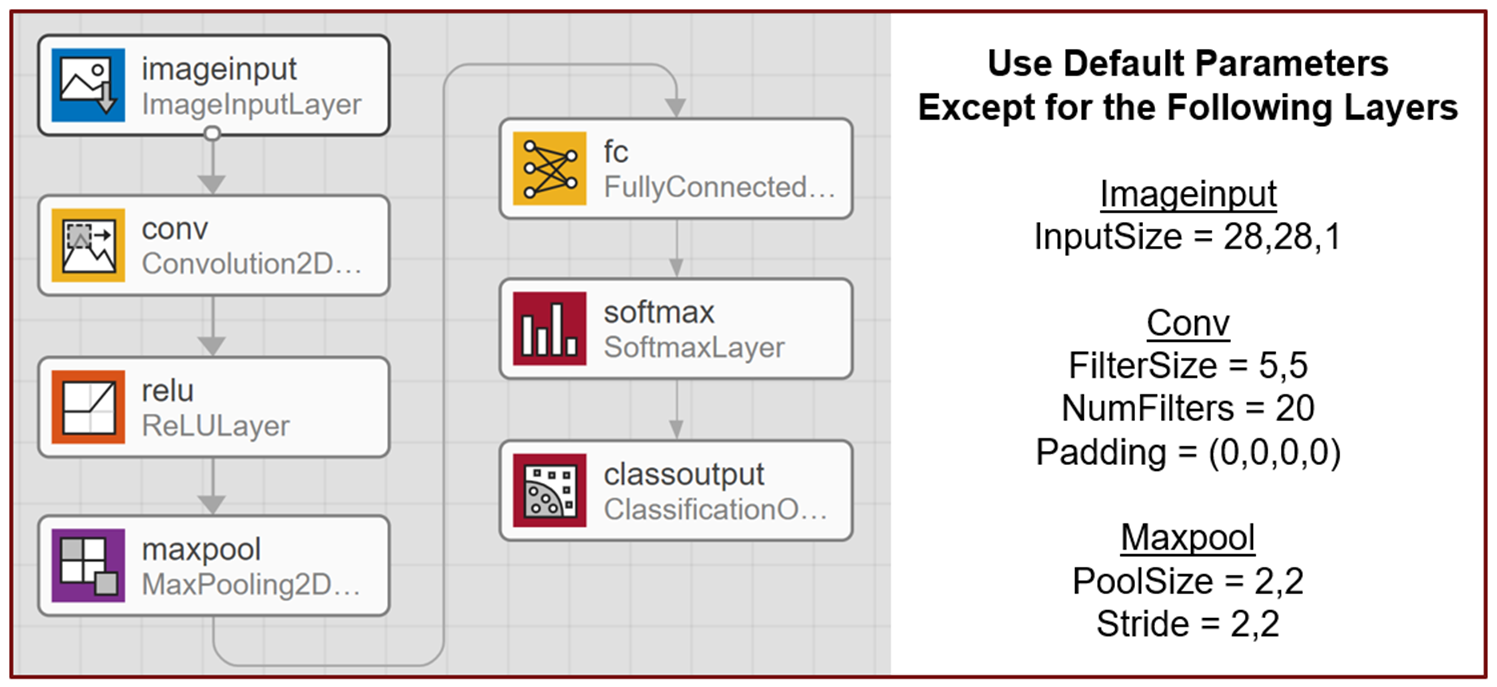

Once you have finished creating the network, export it to the workspace. 

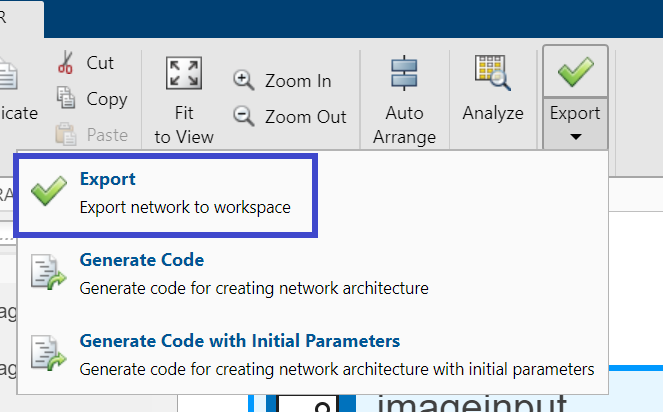

#### Create Architecture without DND (non-Chrome browsers)

If using a different browser, run this section.

layers_1 = [...
    imageInputLayer([28 28 1]), ...
    convolution2dLayer(5, 20), ...
    reluLayer, ...
    maxPooling2dLayer(2, 'Stride', 2), ...
    fullyConnectedLayer(10), ...
    softmaxLayer, ...
    classificationLayer];


## Attempt 1: Set Training Options and Train

[Training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html), AKA hyperparameters, tell our network how to run the training. 

In this section, we will change the max epochs, which controls how many times we pass our training images through the network during training.

- `Set maxEpochs equal to 3`

maxEpochs = 3;
options = trainingOptions('sgdm', ...
    'Plots', 'training-progress', ...    
    'MaxEpochs', maxEpochs);

net1 = trainNetwork(imgDataTrain, labelsTrain, layers_1, options);

## Attempt 2: Change Learning Rate and Train

The network we train tries to minimize a loss function by using an algorithm called gradient descent. The learning rate contributes to whether we can minimize that function.

- Too high - the loss function never converges to a minimum. This is what happened when we used the default learning rate.

- Too low - the loss function converges on a local minima.

options = trainingOptions('sgdm', ...
    'Plots', 'training-progress', ... 
    'MaxEpochs', 3, ...
    'InitialLearnRate', 0.0001); 

net2 = trainNetwork(imgDataTrain, labelsTrain, layers_1, options);

## Attempt 3: Improve Network Architecture and Train

Improving the network architecture can increase training accuracy. This time, we will try a more sophisticated network architecture.

This network has multiple convolution layers, as well as [batch normalization](matlab:doc batchNormalizationLayer) layers, which improve the quality and convergence rate of the training.

layers_3 = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3, 16, 'Padding', 1)
    
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 1)
    
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 64, 'Padding', 1)
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'MaxEpochs', 3, ...
    'Plots', 'training-progress');

net3 = trainNetwork(imgDataTrain, labelsTrain, layers_3, options);

## Evaluate Network Accuracy

Use the [`classify`](https://www.mathworks.com/help/deeplearning/ref/classify.html) command to classify the test dataset

predLabelsTest = classify(net3, imgDataTest);

testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

## View Results

randIndx = randi(numel(labelsTest));
img = imgDataTest(:, :, 1, randIndx);
actualLabel = labelsTest(randIndx);

Display image and prediction

predictedLabel = classify(net3, img);
imshow(img)
truesize([100 35])
title({['Predicted: ' char(predictedLabel)], ['Actual: ' char(actualLabel)]})